% Desired signal
N = 1000;
n = linspace(0,N-1,N);
ws = pi/6;
s = cos(ws*n);

% Added noise
noise = wgn(1,N,-60);
sn = s + noise;

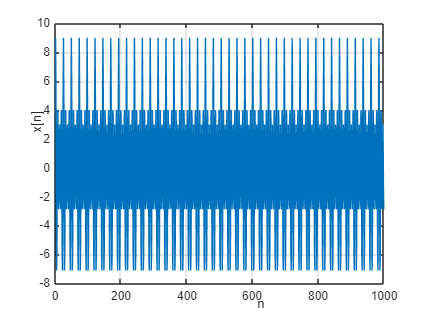

% Interference signals
w1 = pi/3;
w2 = pi/4;
i1 = 5*cos(w1*n);
i2 = 3*cos(w2*n);
x = sn + i1 + i2;
figure
plot(x)
xlabel('n')
ylabel('x[n]')
title('Signal + 2 Interference Signals')
grid on

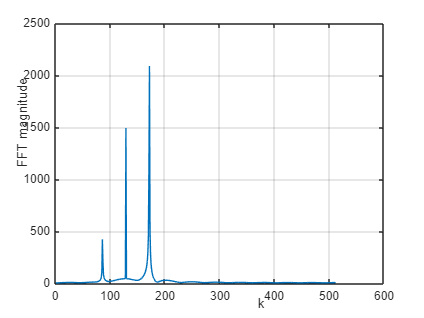

sifft = fft(x,1024);
sifft = sifft(1:end/2);

figure
plot(abs(sifft))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Signal + 2 Interference Signals')
grid on

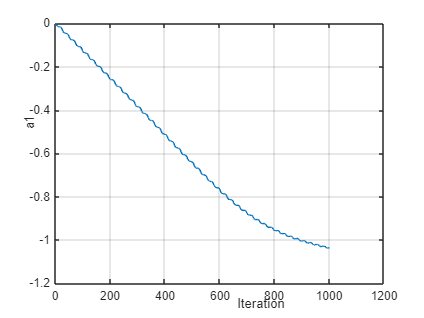

% Remove interference at pi/3
r = 0.85;
u = 0.000085;

a1 = zeros(1,N);
y1 = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y1(i) = e;
        a1(i+1) = a1(i);
    elseif i==2
        e = x(i) + a1(i)*x(i-1);
        y1(i) = e - r*a1(i)*y1(i-1);
        a1(i+1) = a1(i) - u*y1(i)*x(i-1);
    else
        e = x(i) + a1(i)*x(i-1) + x(i-2);
        y1(i) = e - r*a1(i)*y1(i-1) - r^2*y1(i-2);
        a1(i+1) = a1(i) - u*y1(i)*x(i-1);
    end
    if abs(a1(i+1)) > 2
        a1(i+1) = 0;
    end
end

num = [1 a1(end) 1];
den = [1 r*a1(end) r^2];

figure
plot(a1)
xlabel('Iteration')
ylabel('a1')
title('Evolution of a1, w1=\pi/3, r=0.85, and u=0.000085')
grid on

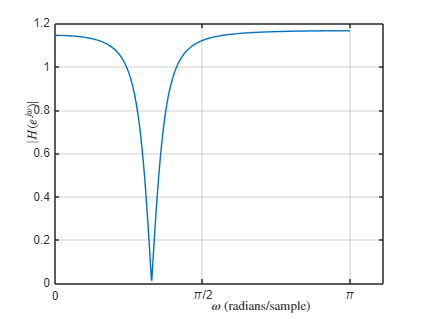


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/3, r=0.85, and u=0.000085')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

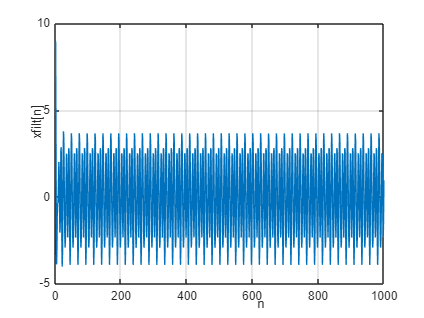


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w0=\pi/3, r=0.85, and u=0.000085')
grid on

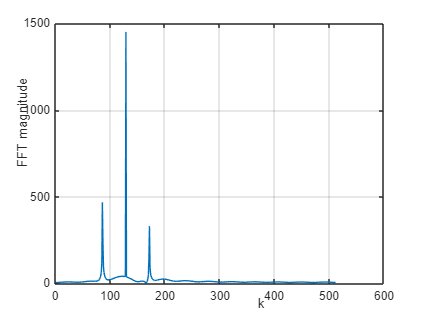


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with w0=\pi/3, r=0.85, and u=0.000085')
grid on

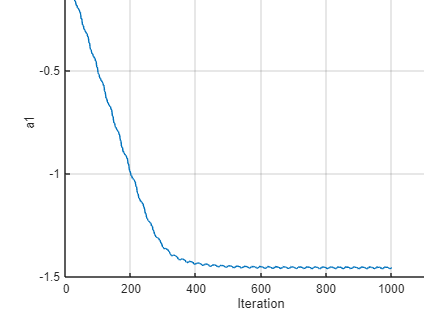

% Remove interference at pi/4
r = 0.85;
u = 0.001;

a2 = zeros(1,N);
y2 = zeros(1,N);

for i=1:N
    if i==1
        e = xfilt(i);
        y2(i) = e;
        a2(i+1) = a2(i);
    elseif i==2
        e = xfilt(i) + a2(i)*xfilt(i-1);
        y2(i) = e - r*a2(i)*y2(i-1);
        a2(i+1) = a2(i) - u*y2(i)*xfilt(i-1);
    else
        e = xfilt(i) + a2(i)*xfilt(i-1) + xfilt(i-2);
        y2(i) = e - r*a2(i)*y2(i-1) - r^2*y2(i-2);
        a2(i+1) = a2(i) - u*y2(i)*xfilt(i-1);
    end
    if abs(a2(i+1)) > 2
        a2(i+1) = 0;
    end
end

num = [1 a2(end) 1];
den = [1 r*a2(end) r^2];

figure
plot(a2)
xlabel('Iteration')
ylabel('a1')
title('Evolution of a2, w2=\pi/4, r=0.85, and u=0.001')
grid on

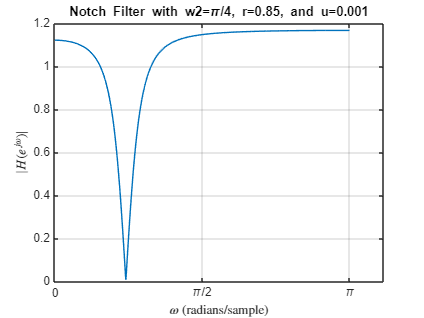


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w2=\pi/4, r=0.85, and u=0.001')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

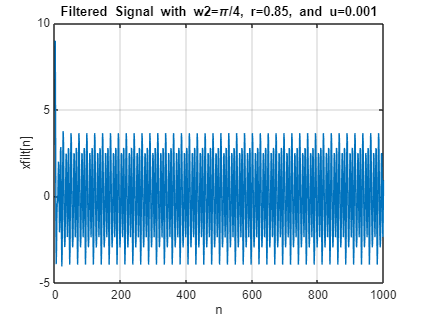


xfiltfilt = filter(num,den,xfilt);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w2=\pi/4, r=0.85, and u=0.001')
grid on

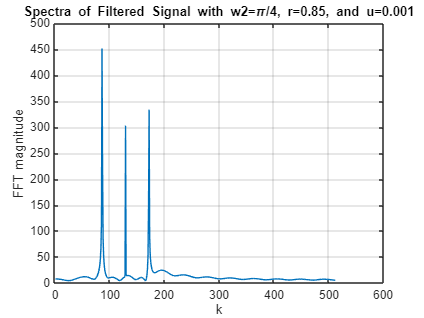


xfiltfft = fft(xfiltfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with w2=\pi/4, r=0.85, and u=0.001')
grid on